# `boxplotGroup` examples

Source: [File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/74437-boxplotgroup)

Author: [Adam Danz](https://www.mathworks.com/matlabcentral/profile/authors/3753776)

Last update: 27-Apr-2021 with `boxplotGroup` vs 2.0.0. 

*This demo is designed to be run in Matlab r2020b or later.* 

## `boxplotGroup(x)`

Create groupped boxplots.  `x` is a 1xm cell array that creates m groups of boxplots. Each element of `x` is a matrix with n columns for n boxes per group. 

Produce 3 groups, each containing 4 boxes. 

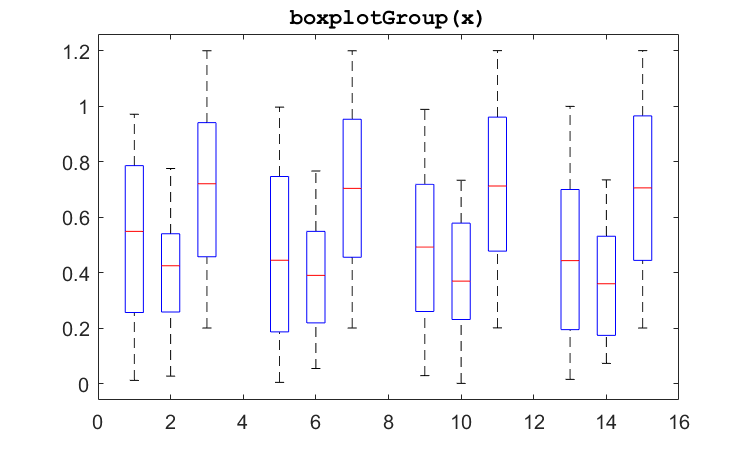

rng('default')
x = {rand(100,4),  rand(20,4)*.8,  rand(1000,4)+.2};

figure('Position',[400 75 500 300])
boxplotGroup(x)
title('boxplotGroup(x)','FontName','FixedWidth')

## `boxplotGroup(ax,x,___)`

Specify axis handle using the same data above.

x1 = {rand(100,4),  rand(20,4)*.8};
x2 = {rand(1000,4)+.2, rand(200,4)*.6, rand(200,4)*.4};
figure('Position',[400 75 500 300])
ax(1) = subplot(2,1,1);
ax(2) = subplot(2,1,2);
boxplotGroup(ax(1), x1)
boxplotGroup(ax(2), x2)
title(ax(1),'boxplotGroup(ax,x)','FontName','FixedWidth')

Add custom labels to the center of each group. The anonymous function `groupCenters` computes the x coordinates to the center of each group. 

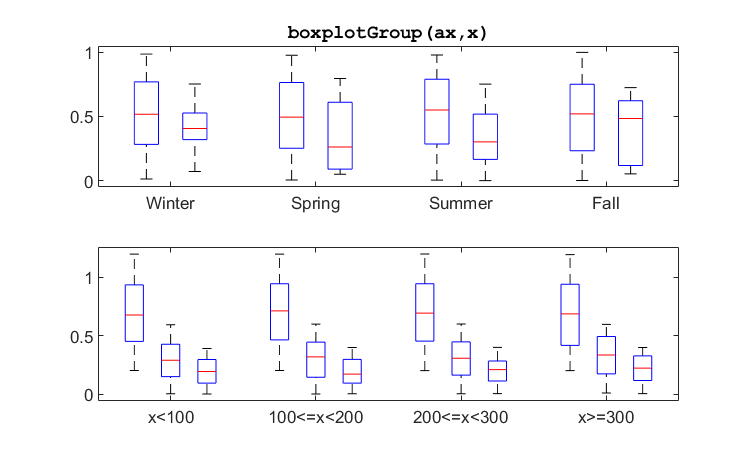

% groupCenters() finds the x coordinate to the center of each group.
% * nGroups: number of groups.
% * nMembers: number of members to each group
% * interGroupSpace: gap between groups (1 by default)
groupCenters = @(nGroups,nMembers,interGroupSpace) ...
    nGroups/2+.5 : nGroups+interGroupSpace : (nGroups+interGroupSpace)*nMembers-1;

x1CenterTicks = groupCenters(numel(x1), size(x1{1},2), 1);
set(ax(1),'XTick',x1CenterTicks,'XTickLabels',{'Winter','Spring','Summer','Fall'})

x2CenterTicks = groupCenters(numel(x2), size(x2{1},2), 1);
set(ax(2),'XTick',x2CenterTicks,'XTickLabels',{'x<100','100<=x<200','200<=x<300','x>=300'})

## `boxplotGroup(__,'interGroupSpace',d)`

Control the spacing between groups.  d is a positive integer. 

Separate groups by 2 and 5 units. 

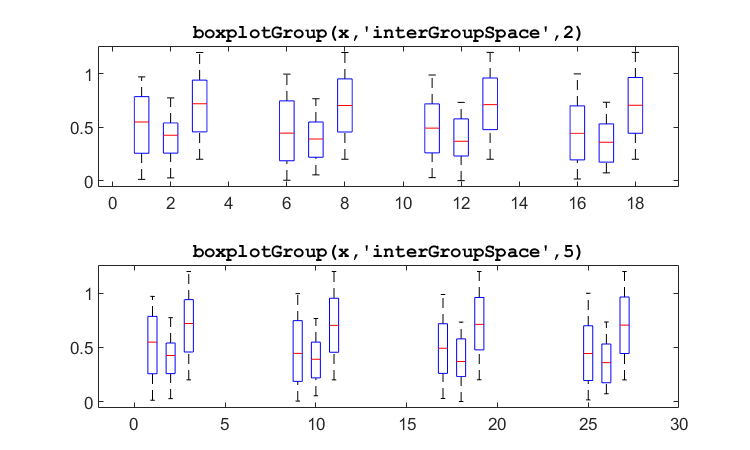

figure('Position',[400 75 500 300])
subplot(2,1,1)
boxplotGroup(x,'interGroupSpace',2)
title('boxplotGroup(x,''interGroupSpace'',2)','FontName','FixedWidth')
subplot(2,1,2)
boxplotGroup(x,'interGroupSpace',5)
title('boxplotGroup(x,''interGroupSpace'',5)','FontName','FixedWidth')

## `boxplotGroup(__,'groupLines',TF)`

Add vertical divider lines between groups. 

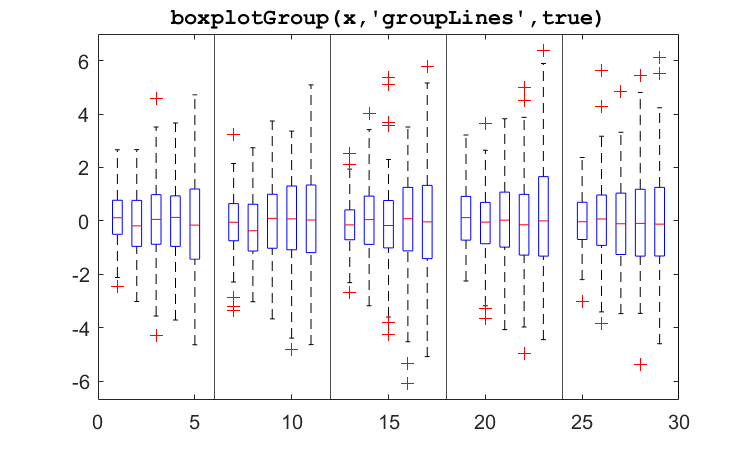

data = randn(200,25).*linspace(1,2,25);
x = mat2cell(data,200,[5 5 5 5 5]);
figure('Position',[400 75 500 300])
boxplotGroup(x,'groupLines',true)
title('boxplotGroup(x,''groupLines'',true)','FontName','FixedWidth')

## `boxplotGroup(__,'primaryLabels',c)`

Provide labels for each box or apply the same set of labels to each group of boxes.  

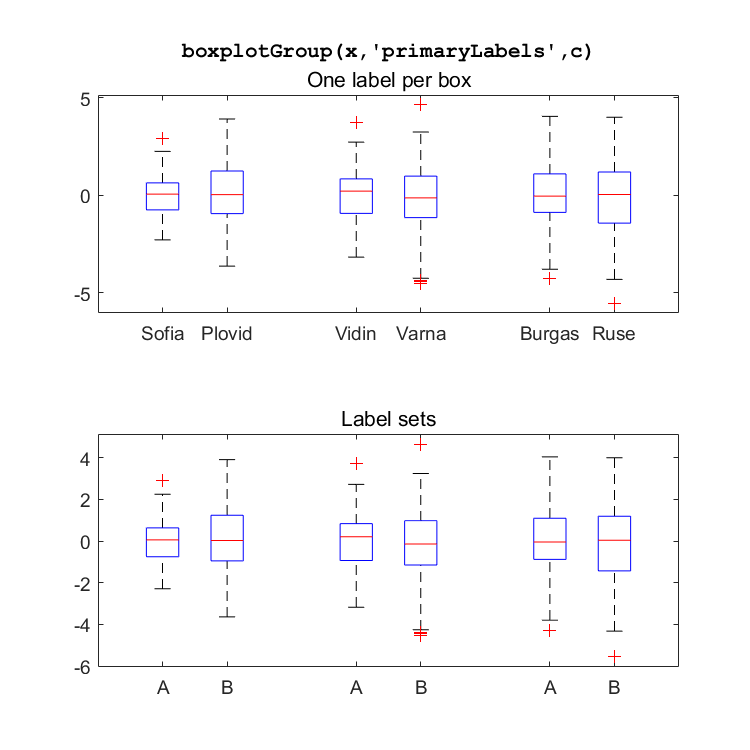

data = randn(200,6).*linspace(1,2,6);
x = {data(:,1:3), data(:,4:6)};

figure('Position',[400 75 500 500])
subplot(2,1,1)
labels = {'Sofia','Plovid','Vidin','Varna','Burgas','Ruse'};
boxplotGroup(x,'PrimaryLabels',labels)
title('boxplotGroup(x,''primaryLabels'',c)','FontName','FixedWidth')
subtitle('One label per box')

subplot(2,1,2)
labelset = {'A', 'B'};
boxplotGroup(x,'PrimaryLabels',labelset)
subtitle('Label sets')

## `boxplotGroup(__,'secondaryLabels',s)`

Label groups. Group labels will be under primary labels by default, even if no primary labels are defined.  If all primary labels are empty, the secondary labels will be shifted upward.  

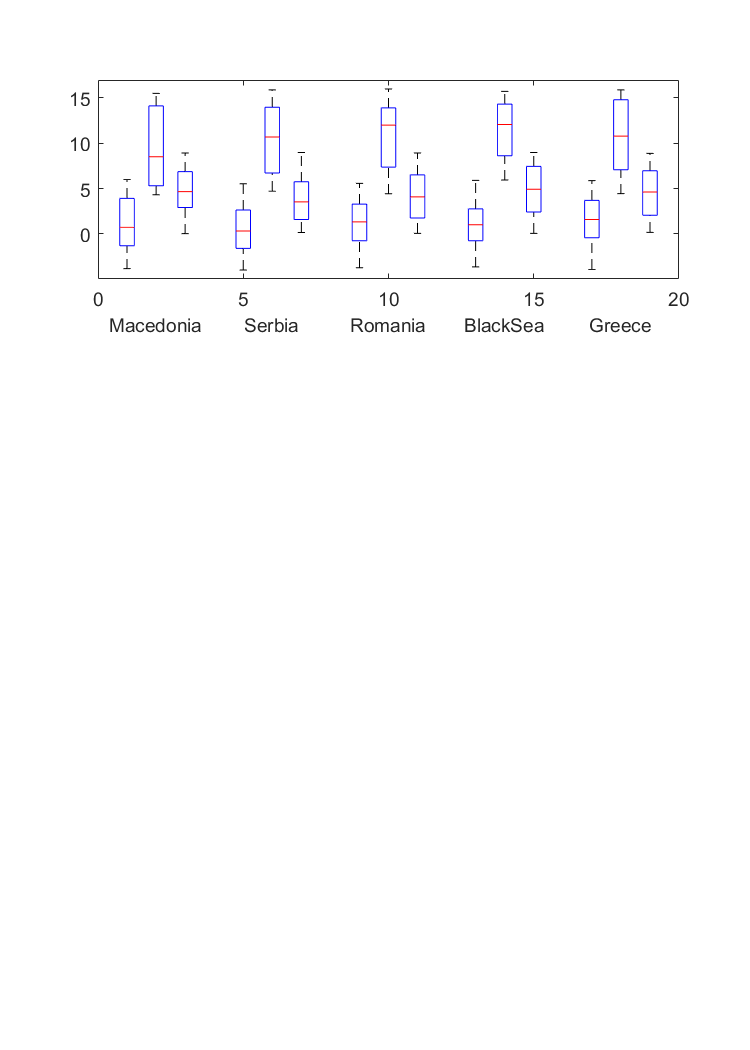

x = {rand(50,5)*10-4,  rand(20,5)*12+4,  rand(80,5)*9};
labels = {'A','B','C'};
grpLabels = {'Macedonia','Serbia','Romania','BlackSea','Greece'};

figure('Position',[400 75 500 700])
ax = subplot(3,1,1);
boxplotGroup(x,'SecondaryLabels',grpLabels)
title('boxplotGroup(x,''secondaryLabels'',c)','FontName','FixedWidth')
subtitle('Secondary labels (Primary labels not specified)')
ax.Position(4) = ax.Position(4)*.9;  % room for title

subplot(3,1,2);
boxplotGroup(x,'primaryLabels',{'','',''},'SecondaryLabels',grpLabels)
subtitle('Secondary labels with empty Primary labels')

subplot(3,1,3)
boxplotGroup(x,'primaryLabels',labels,'SecondaryLabels',grpLabels)
subtitle('Primary and Secondary labels')

## `boxplotGroup(__,'groupLabelType', str)`

Specifies the placement of the secondaryLabels.  Three subplots below show all three options.  This parameter can be combined with `GroupLines` to include group line separators that are not labeled.  

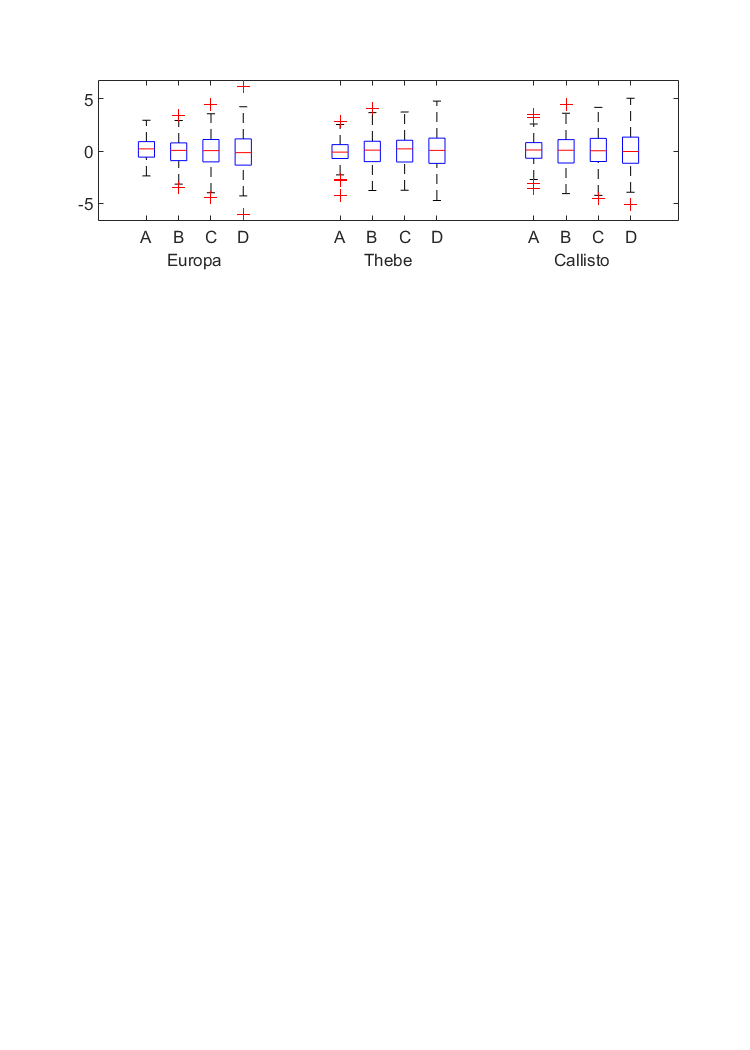

data = randn(200,12).*linspace(1,2,12);
x = mat2cell(data,200,[3 3 3 3]);
labels = ["A" "B" "C" "D"];
grpLabels = ["Europa","Thebe","Callisto"];

figure('Position',[400 75 500 700])
subplot(4,1,1)
boxplotGroup(x,'PrimaryLabels',labels,'SecondaryLabels',grpLabels,...
    'interGroupSpace',2,'groupLabelType','Horizontal');
title('GroupType=''Horizontal''','FontName','FixedWidth')

subplot(4,1,2)
boxplotGroup(x,'PrimaryLabels',labels,'SecondaryLabels',grpLabels,...
    'interGroupSpace',2,'groupLabelType','Vertical');
title('GroupType=''Vertical''','FontName','FixedWidth')

subplot(4,1,3)
boxplotGroup(x,'PrimaryLabels',labels,'SecondaryLabels',grpLabels,...
    'interGroupSpace',2,'groupLabelType','Both');
title('GroupType=''Both''','FontName','FixedWidth')

subplot(4,1,4)
boxplotGroup(x,'PrimaryLabels',labels,'SecondaryLabels',grpLabels,...
    'interGroupSpace',2,'groupLabelType','Horizontal','GroupLines',true);
title('GroupType=''Horizontal''; GroupLines=true','FontName','FixedWidth')

## `boxplotGroup(__,'Colors', ___,'GroupType',type) `

Specify boxplot colors. 

`Colors`

See [`boxplot` documentation](https://www.mathworks.com/help/stats/boxplot.html#d123e141054). 

`GroupType`

When multiple colors are provided, `GroupType` determined whether colors should be applied within or between groups.  

- `'betweenGroups'` assigns color `n` to the n^th box within each group (default). Each group will have the same sequence of colors.

- `'withinGroups'` assigns color `n` to all boxes within the n^th group.  Each group will have its own color. 

Extra color values are ignored. 

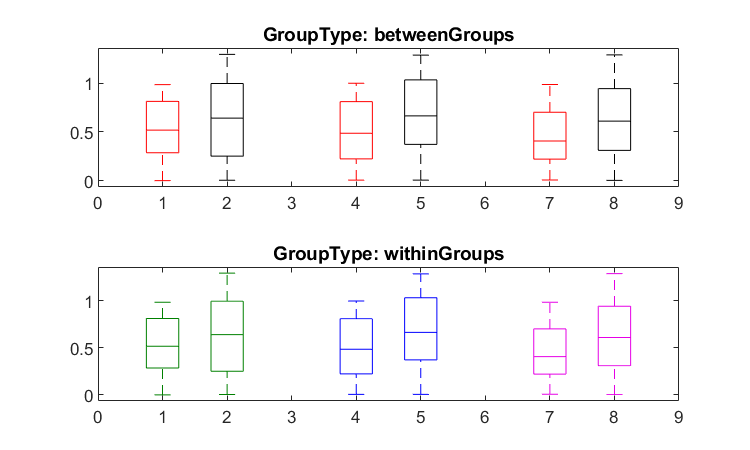

x = {rand(100,3), rand(120,3)*1.3};
figure('Position',[400 75 500 300])
subplot(2,1,1)
boxplotGroup(x,'Colors','rk','GroupType','betweenGroups') % default
title('GroupType: betweenGroups')

subplot(2,1,2)
boxplotGroup(x,'Colors',[0 .5 0; 0 0 1; .9 0 .9],'GroupType','withinGroups')
title('GroupType: withinGroups')

## `boxplotGroup(__, 'PARAM1', val1, 'PARAM2, val2, ...) `

Specify additional `boxplot` name-value pairs. 

`boxplotGroup` is not designed to work with the [grouping options](https://www.mathworks.com/help/stats/boxplot.html#d123e141598) associated with the [`boxplot(x,g)`](https://www.mathworks.com/help/stats/boxplot.html#d123e140818) syntax and a few other parameters.  

Accepted `boxplot` parameters are `BoxStyle, Colors, MedianStyle, Notch, OutlierSize, PlotStyle, Symbol, Widths, DataLim, ExtremeMode, Jitter,` and `Whisker`.

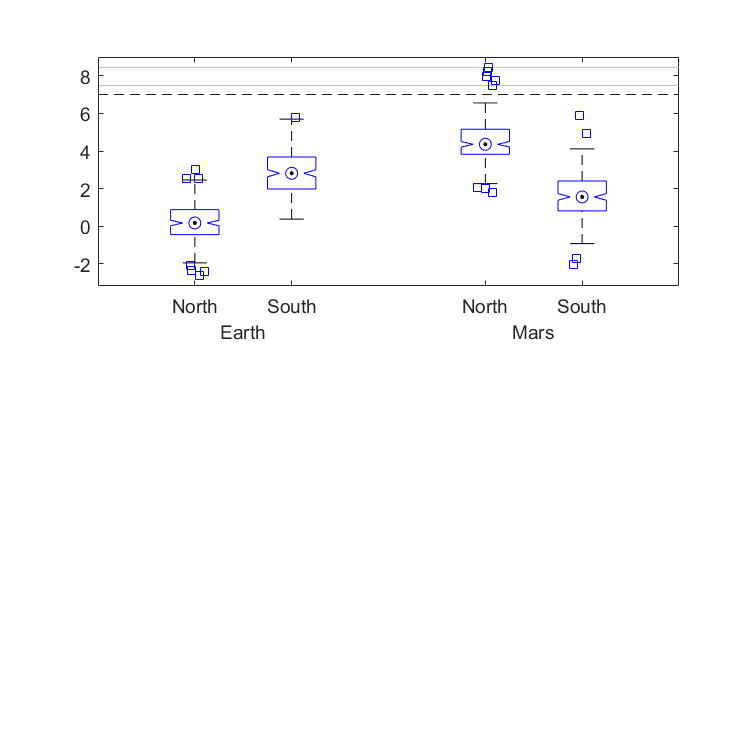

data = randn(200,25).*linspace(1,2,25)+rand(1,25)*5;
x0 = mat2cell(data,200,[5 5 5 5 5]); 
x1 = mat2cell(data(:,1:4),200,[2,2]);
bpColors = cool(5);

figure('Position',[400 75 500 500])
subplot(2,1,1)
boxplotGroup(x1,'PrimaryLabels',{'North','South'}, ...
'SecondaryLabels', {'Earth','Mars'}, ...
'MedianStyle','target','Notch','on', 'OutlierSize',5,...
'Symbol','s','Widths',.5,'DataLim',[-3,7],...
'ExtremeMode','compress','jitter',0.5,'Whisker',1.2)
title('boxplot name-value pairs')

subplot(2,1,2)
boxplotGroup(x0, 'PrimaryLabels', {'A','B','C','D','E'}, ...
'SecondaryLabels',{'NW','NE','CENTER','SE','SW'}, ...
'PlotStyle','Compact','BoxStyle','filled',...
'Colors',bpColors,'GroupType','withinGroups')

## `h = boxplotGroup(__)`

The `boxplotGroup` output is a structure containing handles to graphics objects produced within the function.  The fields therefore depend on the input options. 

Using data from the previous example, make changes to the plot after its rendered. 

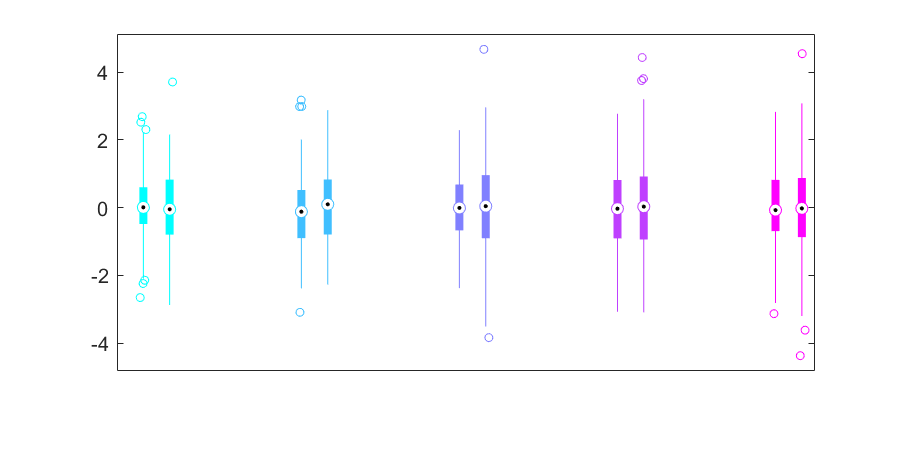

h = struct with fields:
            axis: [1×1 Axes]
          figure: [1×1 Figure]
           xline: [1×5 ConstantLine]
    boxplotGroup: [5×1 Group]

data = randn(200,25).*linspace(1,2,25);
x0 = mat2cell(data,200,[5 5 5 5 5]); 
bpColors = cool(5);

figure('Position',[400 75 600 300])
h = boxplotGroup(x0, 'PrimaryLabels', cellstr(char(randi(26,5,3)+64)), ...
'SecondaryLabels',{'NW','NE','CENTER','SE','SW'}, ...
'GroupLabelType','Vertical', 'PlotStyle','Compact',...
'BoxStyle','filled','Colors',bpColors,'GroupType','withinGroups')

Move the vertical labels to the bottom.

set(h.xline,'LabelVerticalAlignment','bottom')

Change to color of the median points. 

medOuter = findobj(h.boxplotGroup,'tag','MedianOuter');
set(medOuter,'MarkerFaceColor', 'k')
medInner = findobj(h.boxplotGroup,'tag','MedianInner');
set(medInner,'MarkerEdgeColor', 'w')

Change outlier symbol.

outliers = findobj(h.boxplotGroup,'Tag','Outliers');
set(outliers, 'Marker','*')

Change width of whiskers.

set(findobj(h.boxplotGroup,'tag','Whisker'),'LineWidth',1)

Rotate xtick labels and font.

h.axis.XTickLabelRotation = 90; 
h.axis.XAxis.FontName = 'fixedwidth';
h.axis.XAxis.FontWeight = 'bold';

Set the background color for each group.

groupX = [cell2mat(get(h.xline,'value'));max(xlim(h.axis))];
yl = ylim(h.axis);
ph = gobjects(1,numel(groupX)-1);
for g = 1:numel(groupX)-1
    ph(g) = patch(h.axis, ...
        groupX(g+[0,1,1,0]),...
        yl([1,1,2,2]),...
        bpColors(g,:),...
        'FaceAlpha',0.1,...
        'LineStyle','none');
end
uistack(ph,'bottom')

Turn on horizontal grid

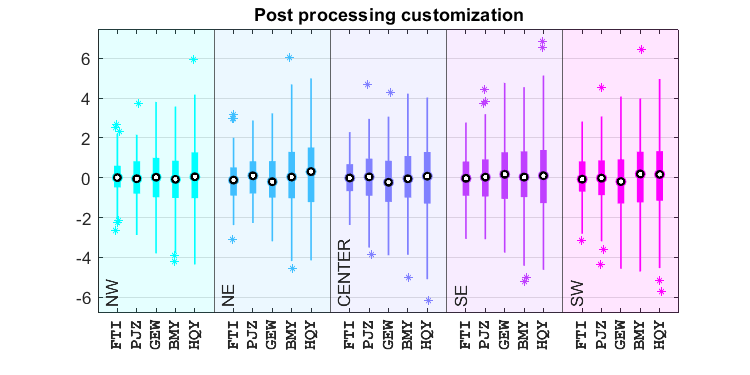

h.axis.YGrid = 'on';
title('Post processing customization')